# 1D Muscle Model based on the **Hill** 3-Element Model

clear all

## GL_RESTbal pL_RESTtting options

fnum = 1;
opt_grid = 'on';
opt_hold =  'on';
splotx = 0;
sploty = 0;

## GL_RESTbal muscle properties

$L_{rest}$ is the muscle resting length, $P_{max}$ is the maximum force the muscle can produce and $v_{max}$ is the maximum velocity of shortening.

L_REST = 0.5; %mm
Pmax = 100; %N
Vmax = 2; %mm/s

$a$ and $b$ are shape constants for the muscle force-velocity relationship

% muscle model constants
a = 0.25;
b = a*Vmax/Pmax;

## Passive elastic element

This element represents the passive response of the muscle upon streching greater than resting length.

Note that $L_{PE}=L_{TOT}=L_{CE}$

The form of the passive relationship is not easily found in literature and is implemented in a straight forward way here to match the requirements of an exponential form which is non-zero above $L_{rest}$. Parameter $c$ is introduced to tune the shape of the curve. 

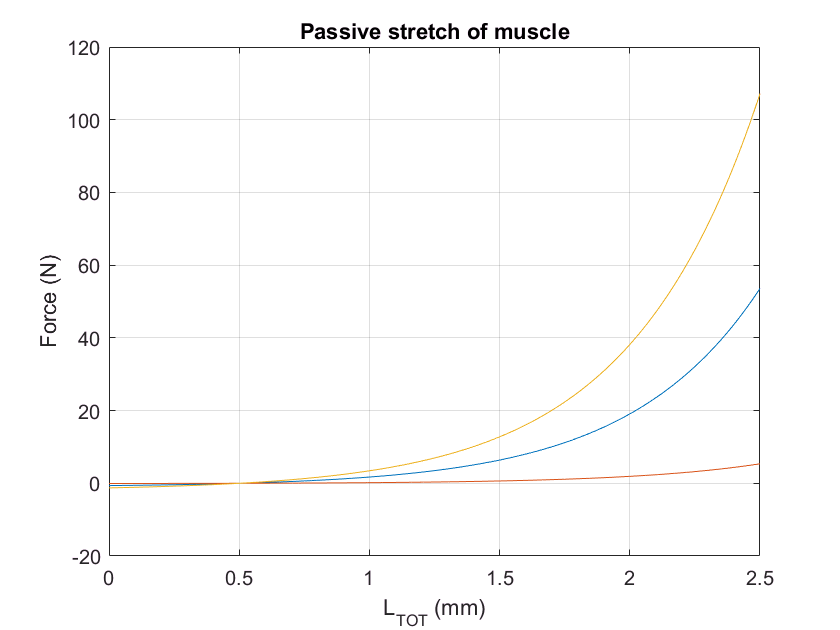

c = 0.5;
L_TOT = (0:0.001:L_REST*5);
F_PE = c*(exp(L_TOT/L_REST-1)-1); 

xvec = L_TOT;
yvec = F_PE;
ftitle = 'Passive stretch of muscle';
xtitle = 'L_{TOT} (mm)';
ytitle = 'Force (N)';
plotxy(xvec, yvec, fnum, ftitle, xtitle, ytitle, opt_grid, opt_hold, ...
    splotx, sploty)

## Isometric contraction

Here an isometric contraction is considered. 

t = 0:0.01:(Vmax*100)/a;
P_iso = Pmax*(1-exp(-(b/L_REST)*t));

fnum = fnum+1;
xvec = t;
yvec = P_iso;
ftitle = 'Isometric force output of muscle';
xtitle = 'time (s)';
plotxy(xvec,yvec, fnum, ftitle, xtitle, ytitle, opt_grid, opt_hold, ...
    splotx, sploty)

## constant velocity

recall that v = dL_ce/dt

v = 0.01;
P_constvel = (b*Pmax-a*v)/(b+v)*abs(1-exp(-t*(b+v)/L_REST));

fnum = fnum+1;
yvec = P_constvel;
ftitle = ['Constant velocity of CE: ', num2str(v), ' mm/s'];
xtitle = 'time (s)';
plotxy(xvec,yvec, fnum, ftitle, xtitle, ytitle, opt_grid, opt_hold, ...
    splotx, sploty)

## force-velocity relationship

t tends to inifinty & exponential term in above equation drops out range of velocities

v = 0:0.01:2;
P_varyvel = (b*Pmax-a*v)./(b+v);
P_varyvel_norm = P_varyvel/Pmax;

fnum = fnum+1;
xvec = v;
yvec = P_varyvel_norm;
ftitle = 'Force-velocity contraction of muscle';
xtitle = 'veL_RESTcity (mm/s)';
plotxy(xvec,yvec, fnum, ftitle, xtitle, ytitle, opt_grid, opt_hold, ...
    splotx, sploty)

## force-length relationship

recall that L_tot = L_ce + L_se

L_tot = (0.5*L_REST):0.01:(L_REST*1.5);
Lnorm = L_tot/L_REST;
SK = 0.25;
P_length = Pmax*exp(-((Lnorm-1)/SK).^2);
P_length_norm = P_length/Pmax;

fnum = fnum+1;
xvec = L_tot;
yvec = P_length_norm;
ftitle = 'Force-length contraction of muscle';
xtitle = 'L_{tot} = L_{ce}+L_{se} (mm)';
plotxy(xvec,yvec, fnum, ftitle, xtitle, ytitle, opt_grid, opt_hold, ...
    splotx, sploty)

## total muscle force

here the 2-element model is implemented (the SE is ignored, seee Zajac (1989))